# Interface Métodos Numéricos para ED/PVI

## 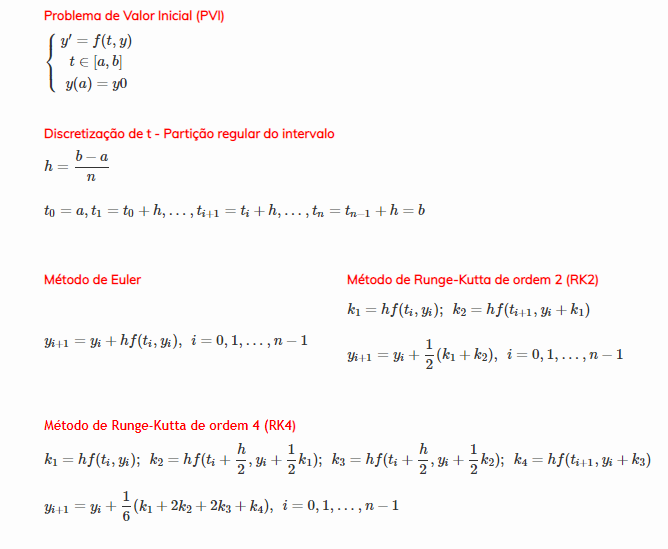

26/03/2021     Arménio Correia     armenioc@isec.pt

### **Adaptado por:**

Nuno  Alexandre Domingues             a2020109910@isec.pt

Miguel Ferreira Neves                       a2020146521@isec.pt

Daniel Duarte Dias Ferreira Albino    a2020134077@isec.pt

Data: 15/04/2021    

Método de Adams - Bashforth de ordem 4 (Passo múltiplo):

clear 
syms y(t) % Declaração de variáveis simbólicas


%Validação dos campos de entrada
while 1         
    strF = "y*(2.128-0.0432*y)";
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

while 1     
    a = 0;
    if (~isempty(a) && isscalar(a) && isreal(a)) 
    break
    end
end

while 1
    b = 5;
    if (~isempty(b) && isscalar(b) && isreal(b) && b>a) 
    break
    end
end


    n = 10;

while 1
    y0 = 0.24;
    if (~isempty(y0) && isscalar(y0) && isreal(y0)) 
    break
    end
end
       
% Atribuição de vetores para guardar os valores retornados pelas funções
yEuler = NEuler(f,a,b,n,y0);
yEulerM = NEulerM(f,a,b,n,y0);
yRK2 = NRK2(f,a,b,n,y0);
yRK4 = NRK4(f,a,b,n,y0);
yODE45 = NODE45(f,a,b,n,y0);
yNAdams = NAdams(f,a,b,n,y0);

% Solução exata
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);

% Cálculo de erros dos métodos numéricos em relação à solução exata
erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroODE45 = abs(yExata-yODE45);
erroAdams = abs(yExata-yNAdams);

% Gráfico da solução exata
plot(t,yExata,"-ro")

EscolhaMetodo = "RK4";

switch EscolhaMetodo           
    case "Euler"
        tabela = [t.',yExata.',yEuler.',erroEuler.'];
        %array2table(tabela,"VariableNames",{'t','Exata','Euler','erroEuler'})
        nome_var = {'t','Exata','Euler','erroEuler'};
        hold on
        plot(t,yEuler,"-g*")
        legend('Exata','Euler')
    
    case "EulerM"
        tabela = [t.',yExata.',yEulerM.',erroEuler.'];
        %array2table(tabela,"VariableNames",{'t','Exata','EulerM','erroEulerM'})
        nome_var = {'t','Exata','EulerM','erroEulerM'};
        hold on
        plot(t,yEuler,"-g*")
        legend('Exata','EulerM')
    
    case "RK2"
        tabela = [t.',yExata.',yRK2.',erroRK2.'];
        %array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})
        nome_var = {'t','Exata','RK2','erroRK2'};
        hold on
        plot(t,yRK2,"-g*")
        legend('Exata','RK2')
        
    case "Euler/RK2"    %Acrescentado para resolver o exercício 3.(C)
        tabela = [t.',yExata.',yEuler.',yRK2.',erroEuler.',erroRK2.'];
        %array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})
        nome_var = {'t','Exata','Euler','RK2','erroEuler','erroRK2'};
        hold on
        plot(t,yEuler,"-g*")
        plot(t,yRK2,"-mo")
        legend('Exata','Euler','RK2')
        
    case "RK4"
        tabela = [t.',yExata.',yRK4.',erroRK4.'];
        %array2table(tabela,"VariableNames",{'t','Exata','RK4','erroRK4'})
        nome_var = {'t','Exata','RK4','erroRK4'};
        hold on
        plot(t,yEuler,"-g*")
        legend('Exata','RK4')
    case "ODE_45"
        tabela = [t.',yExata.',yODE45.',erroODE45.'];
        %array2table(tabela,"VariableNames",{'t','Exata','ODE45','erroODE45'})
        nome_var = {'t','Exata','ODE45','erroODE45'};
        hold on
        plot(t,yODE45,"-b*")  
        legend('Exata','ODE45')
    case "NA"
        tabela = [t.',yExata.',yNAdams.',erroAdams.'];
        %array2table(tabela,"VariableNames",{'t','Exata','Adams','erroAdams'})
        nome_var = {'t','Exata','Adams','erroAdams'};
        hold on
        plot(t,yNAdams,"-b*")  
        legend('Exata','Adams')
    case "TodosMetodos"                 
        tabela = [t.',yExata.',yEuler.',yEulerM.',yRK2.',yRK4.',yODE45.',yNAdams.',erroEuler.',erroEulerM.',erroRK2.',erroRK4.',erroODE45.',erroAdams.'];
        %array2table(tabela,"VariableNames",{'t','Exata','Euler','EulerMelhorado','RK2','RK4','ODE45','Adams','erroEuler','erroEulerM','erroRK2','erroRK4','erroODE45','erroAdams'})
        nome_var = {'t','Exata','Euler','EulerMelhorado','RK2','RK4','ODE45','Adams','erroEuler','erroEulerM','erroRK2','erroRK4','erroODE45','erroAdams'};
        hold on
        plot(t,yEuler,"-b*") 
        plot(t,yEulerM,"-mx") 
        plot(t,yRK2,"-y*")  
        plot(t,yRK4,"-c*")  
        plot(t,yODE45,"-gx")  
        plot(t,yNAdams,"--kx") 
        legend('Exata','Euler','EulerMelhorado','RK2','RK4','ODE45','Adams')
end
array2table(tabela,"VariableNames",nome_var) 

ans = 11×4 table
     t      Exata       RK4      erroRK4 
    ___    _______    _______    ________

      0       0.24       0.24           0
    0.5    0.68913    0.68601    0.003119
      1     1.9454     1.9288    0.016637
    1.5     5.2446     5.1856    0.059016
      2     12.644     12.501     0.14288
    2.5     24.638     24.433     0.20444
      3     36.628     36.462      0.1665
    3.5     44.021     43.902     0.11893
      4     47.316     47.235     0.08141
    4.5     48.571     48.525    0.046517
      5      49.02     48.996    0.023084


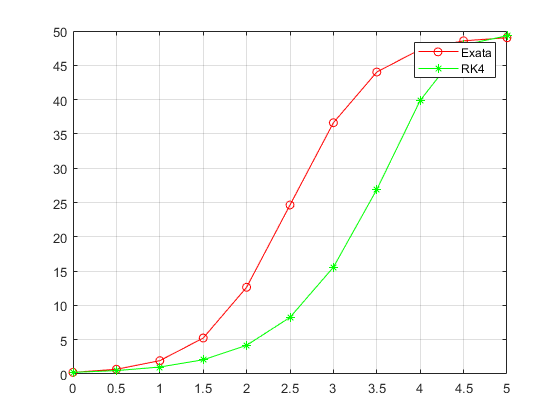

grid on
hold off